clear

# Laplace operator on a disk

N = 25;
M = 20;
[r, a, rr, aa I, D1r, D2r, D3r, D4r, D2a, D4a, bc] = get_operators(N, M);

Laplace operator

L = D2r + D1r./rr + D2a./rr.^2;
% boundary condition
L = bc(L);

Compute eigenvalues

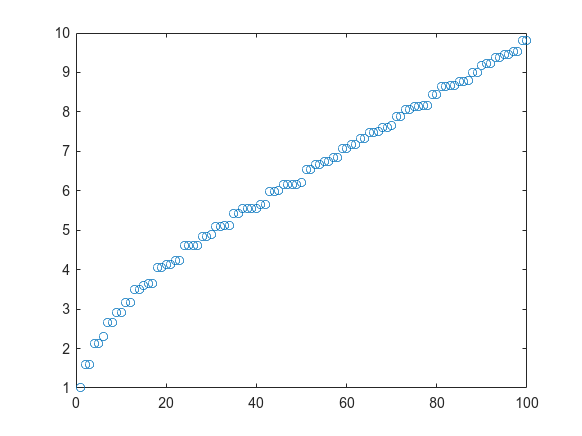

[V, lam] = eig(-L); 
lam = diag(lam); 
[lam,ii] = sort(lam);
V = V(:,ii);
lam = sqrt(lam/lam(1));
plot(real(lam), 'o')
xlim([0, 100])

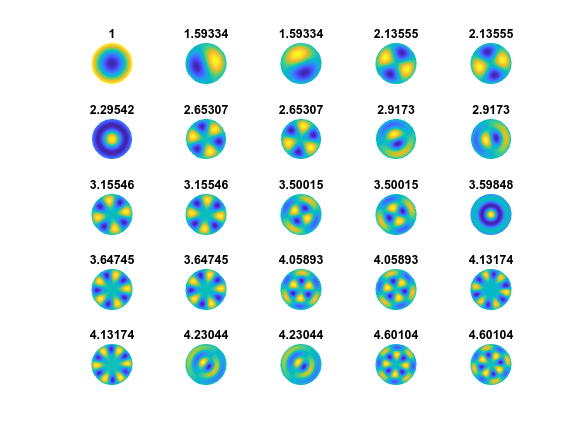

figure
for i = 1:25
    subplot(5,5,i)
    my_plot(r(2:end), a, V(:,i))
    axis off
    view([0,90])
    title(lam(i))
end

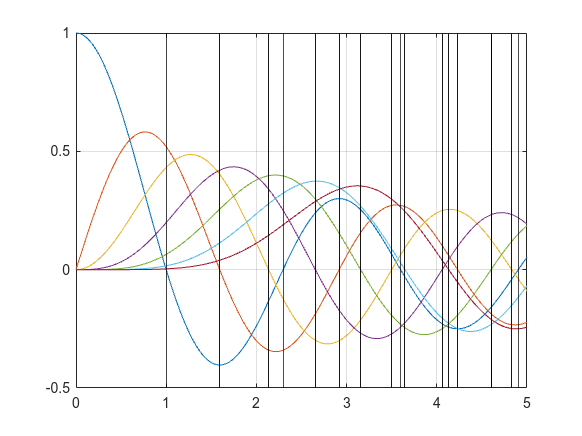

% eigenvalues coeicide with roots of bessel function
z = 0:0.01:5;
figure
for i = 0:6
    plot(z, besselj(i, z*sqrt(5.78319)))
    hold on
end
hold off
xline(real(lam(lam<5)), 'k')
grid on